# Drone Competition: Attempting to identify the red path

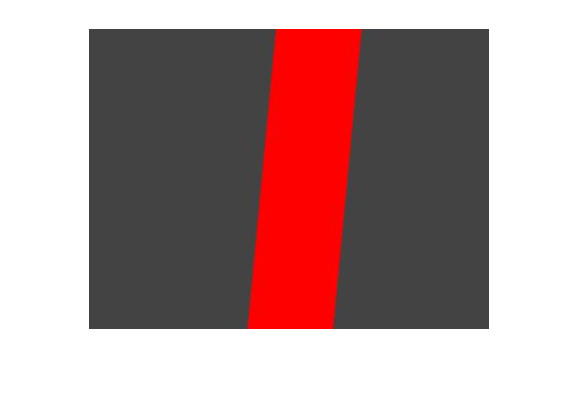

% Method 1: Identifying the straight-line paths using a Hough transform, or
% something of the sorts ...

ImageFromCamera = imread('CameraFeed2.jpg'); % Reading in the image from the camera feed
imshow(ImageFromCamera); % Show me the image - just to ensure it's correct!

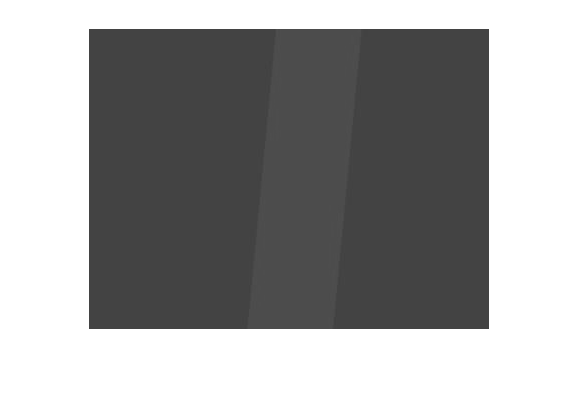


Gray_Image = rgb2gray(ImageFromCamera); % Nice function!
imshow(Gray_Image); % Showing the gray scale image ...

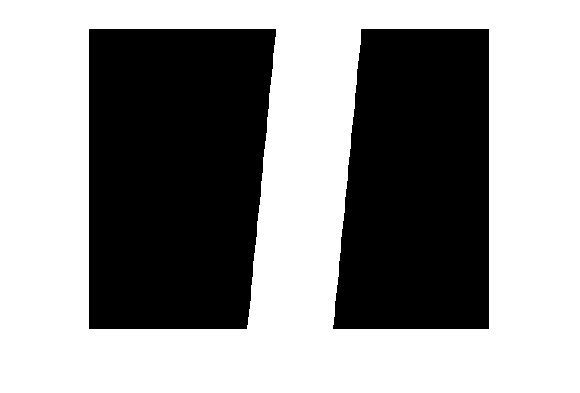


BW_Image = imbinarize(Gray_Image); % Binarizing the gray scale image ... expecting a black and white one
% to result ...
imshow(BW_Image); % Let's see ...


% Let's try and apply the Hough transform:
[H, theta, rho] = hough(BW_Image);


% Let's explore other ways we may be able to solve the problem ...
% Method 2: Turning off all the non-red pixels, and then approximating the
% slope of the remaining red lines (if there are any), as well as the average of their x-values ...
Image = imread('CameraFeed2.jpg');
imshow(Image);

d = size(Image); % Working out the size of the image ... we know already of course, but suppose
% we didn't ...
height = d(1); % The height, in pixels, of the image ...
length = d(2); % And the length of the image in pixels

% Let's create two flag variables ...
flag1 = 0;
flag2 = 0;
flag3 = 0;
flag4 = 0;

leftIdx = 1;
rightIdx = length;

x1 = 0;
x2 = 0;
x3 = 0;
x4 = 0;

while ((flag1 && flag2) == 0)
    
    if(Image(height/3, leftIdx, 1) > 253) % The third entry for 'Image' is 1 as we're only inspecting the intensity of red in the pixel's RGB triplet ...
        flag1 = 1; % We've found the left boarder of the red path ... raise the flag!
        x1 = leftIdx; % The x-coordinate (pixel number) of the leftmost line ...
    else
        leftIdx = leftIdx + 1; % Increment the index number so we can check the next pixel ...
    end
    
    if(Image(height/3, rightIdx, 1) > 253)
        flag2 = 1; % Raise the flag as we've found the boarder for the rightmost red line ...
        x2 = rightIdx;
    else
        rightIdx = rightIdx - 1; % Decrement the index so we can inspect the next pixel to the right ...
    end
end

leftIdx = 1;
rightIdx = length;

while ((flag3 && flag4) == 0)
    
    if(Image(2*height/3, leftIdx, 1) > 253) % The third entry for 'Image' is 1 as we're only inspecting the intensity of red in the pixel's RGB triplet ...
        flag3 = 1; % We've found the left boarder of the red path ... raise the flag!
        x3 = leftIdx; % The x-coordinate (pixel number) of the leftmost line ...
    else
        leftIdx = leftIdx + 1; % Increment the index number so we can check the next pixel ...
    end
    
    if(Image(2*height/3, rightIdx, 1) > 253)
        flag4 = 1; % Raise the flag as we've found the boarder for the rightmost red line ...
        x4 = rightIdx;
    else
        rightIdx = rightIdx - 1; % Decrement the index so we can inspect the next pixel to the right ...
    end
end